**The Gauntlet Challenge (Part 2, Navigating the Gauntlet)**

Joon Kang, Mari Kang 

For our Gauntlet Challenge, we choice Level 3 as our problem to tackle. First off, we identified what obstacles there were and where the position of the BoB was using the lidar scan in the starting point of the NEATO, pre-determined by the assignment. Afterwards, the scanned data was turned into line segments that was connected together for simpler obstruction recognition. The circle, however was identified using the circle fitting function and we recieved the centerpoint and the radius for the BoB. With these data, we created the contour lines by making a scalar feild with the obstrcutions being a sink and the BoB a source. With this, we were able to create a 3-D contour that showed where the NEATO would travel. In this case, the NEATO traveled using the steepest gradient ascent function, where it identifies the quickest way to clinb to the top of the contour. Since we set the obstruction as a sink and the BoB as a source, the we were able to create a path for the NEATO using the gradients. Then the NEATO was simulated using the wheel velocity derived from the gradient heading multipled by the step, which was put into a while loop until it finished the course. The data of the wheels were then collected and put into a function, creating actual plot of where the robot moved. The time and distance traveled was dervied from how long the function ran for, as well as it's accumulation of position heading by using a distance formula of change in position. 

d = 0.235;
x_start = 0;
y_start = 0;
lamda = 0.07;
delta = 1.2;
angle_start = atan2(0,1);
position = [x_start, y_start];
time = 1;

%Equations for partial derivative of Z
[u, v] = gradient(Z);

pub = rospublisher('raw_vel');

% stop the robot if it's going right now
stopMsg = rosmessage(pub);
stopMsg.Data = [0 0];
send(pub, stopMsg);
 
placeNeato(x_start, y_start, 1,0);
% wait a bit for robot to fall onto the bridge
pause(2); 

% time to drive!!


%making the Neato go based off of calculated velocities
%setting up message that send left and right wheel velocities

velMsg = rosmessage(pub); 
distance_traveled = 0;
start = rostime('now'); 
tic
while 1
    current = rostime('now');
    elapsed = current - start;
    % get the current time from ROS
    if elapsed.seconds >= time
        start = current;
        %Equation for the direction of travel
        used_indices=[used_indices, nrstx];
        [~,nrstx] = min(abs(X(:)-x_start));
        [~,nrsty] = min(abs(Y(:)-y_start));
    
        f_grad=[fx(nrsty,nrstx) fy(nrsty,nrstx)];
        f_grad=f_grad./norm(f_grad);
        
        %finding change in position
        move = f_grad*lamda;
        
        %Calculate Total Distance Traveled
        delta_p = sqrt(move(1).^2+move(2).^2)
        distance_traveled = distance_traveled + delta_p
        
        %finding speed
        r_speed = norm(move/(time));
        %calculating direction of gradient
        new_angle = atan2(f_grad(2), f_grad(1));
        %finding angular velocity
        delta_w = (new_angle - angle_start);

        w_speed = delta_w/time;
        angle_start = new_angle;

        %finding linear velocities of each wheel
        V_L = r_speed - (w_speed*(d/2));
        V_R = r_speed + (w_speed*(d/2));

        velMsg.Data = [V_L, V_R]; % set wheel velocities at specific time
        send(pub, velMsg); % send new wheel velocities

        %calculating new position
        position = position + move;
        x_start = position(1);
        y_start = position(2);
        lamda = delta *lamda; 
    
        if norm(f_grad*lamda) > 0.63  %stoping the Neato at the end of the path
            send(pub, stopMsg);
            total_time_elasped = toc
            
            break %leave this loop once we have reached the stopping time
        end
    end
end

distance_traveled;
total_time_elasped;

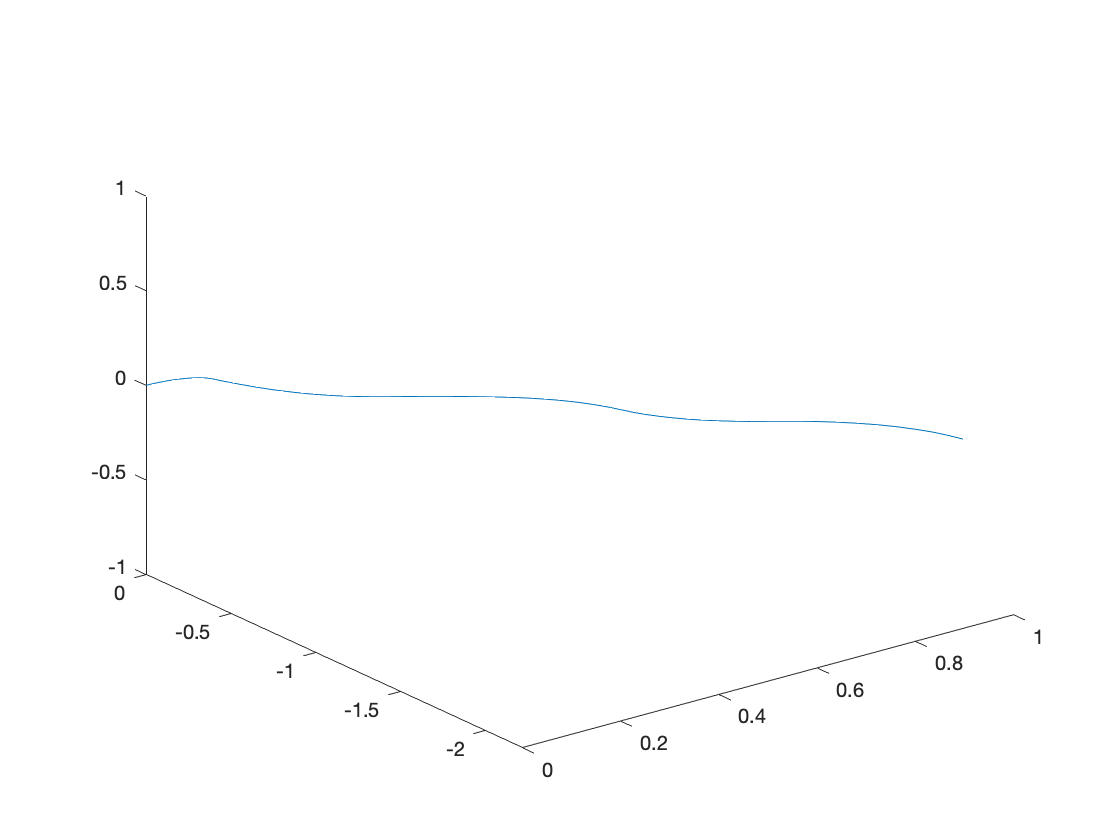

load gauntlet.mat

timeframe=dataset(:,1);
leftpos=dataset(:,2);
rightpos=dataset(:,3);

%Using the equation of velocity=position/time, finding the velocities of
%the left and right wheel.
leftvelo=diff(leftpos)./diff(timeframe);
rightvelo=diff(rightpos)./diff(timeframe);

%With the velocities of each wheel, we can calculate the linear and angular
%velocity
velo_exp=(leftvelo+rightvelo)./2;
angular_exp=(rightvelo-leftvelo)./0.235;


%Setting the starting position and heading of the NEATO
bridgeStart = [0,0,0];
startinggrad = [1,0,0];

%Heading matrix will collect the heading throughout the simulation and
%Position matrix will collect the position throughout the simulation
heading=startinggrad;
position=bridgeStart;

%new_position will consistently update the position and angle variable will
%consistently update the angle
new_position=position;
angle=0;


n=1;
while n < 154
    if n ==1;
        new_angle=angle+angular_exp(n,:)*timeframe(1);
        new_heading=[startinggrad(:,1)*cos(new_angle)-startinggrad(:,2)*sin(new_angle),startinggrad(:,1)*sin(new_angle)+startinggrad(:,2)*cos(new_angle),0];
        new_position=new_position+velo_exp(n,:)*new_heading*timeframe(1);
    else 
        new_angle=angle+angular_exp(n,:)*(timeframe(n)-timeframe(n-1));
        new_heading=[startinggrad(:,1)*cos(new_angle)-startinggrad(:,2)*sin(new_angle),startinggrad(:,1)*sin(new_angle)+startinggrad(:,2)*cos(new_angle),0];
        new_position=new_position+velo_exp(n,:)*new_heading*(timeframe(n)-timeframe(n-1));
    end
    position=cat(1,position,new_position);
    heading=cat(1,heading,new_heading);
    angle=new_angle;
    n=n+1;

end

%3D plot of the experimental path
p=position;
figure()
plot3(p(:,1),p(:,2),p(:,3))

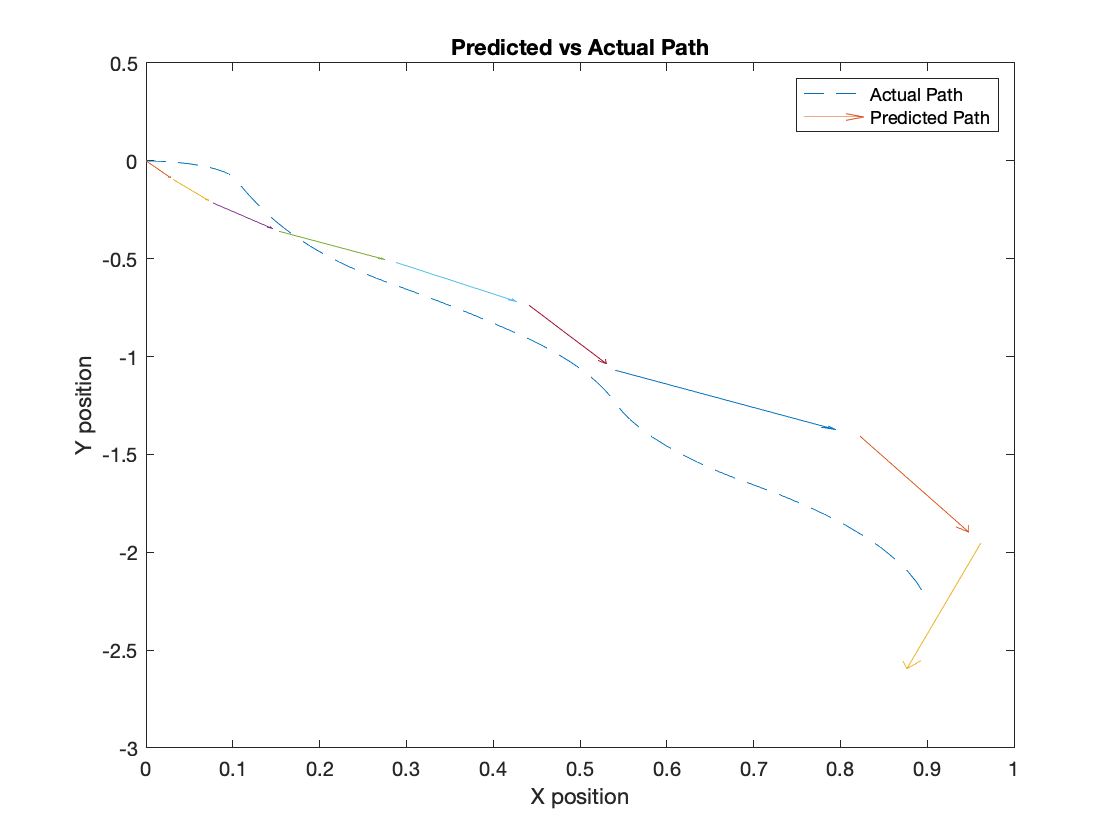


%Plotting the predicted and actual path with several unit tangent vectors
figure()

plot(p(:,1),p(:,2),'--'), hold on
for i=1:size(everyposition,1)
    quiver(everyposition(i,1),everyposition(i,2),everymove(i,1),everymove(i,2))
end

hold off
title('Predicted vs Actual Path')
xlabel('X position')
ylabel('Y position')
legend('Actual Path','Predicted Path')

Total time elapsed for robot to reach BoB: 14.65 seconds

Total distance traveled: 3.47m

Overall, the system worked well. The gradient was set out very clean because of connecting te obstructions in one single pen, and the NEATO never had to move to unnessesary locations due to a mishap between obstacles. The contour looks very nice, and it has a straight path towards the top. The experimental data above shows that the gradient and the actual path opf the NEATO is a little different, but this is because the gradient never considered the distance between wheels or even the size of the robot - this all lead to actual physics being a little different from theoretical physics. However, the path is relativley similar and it is good enough to say that considering the errors that occur between real life and numbers, it is a good representation of the outcome.  

function [fitline_coefs,bestInlierSet,bestOutlierSet,bestEndPoints]= robustLineFit(r,theta,d,n,visualize)
%The [fitline_coefs,bestInlierSet,bestOutlierSet,bestEndPoints]= robustLineFit(r,theta,d,n) 
%function runs the RANSAC algorithm for n candidate lines and a threshold of d. The inputs r and
%theta are polar coordinates. The output fitline_coefs are the coefficientsmatlab:matlab.internal.language.introspective.errorDocCallback('TheGauntlet>robustLineFit', 'C:\Users\mkang1\Desktop\QEA\Robo\Gauntlet\TheGauntlet.mlx', 186)
%of the best fit line in the format [m b] where y=m*x+b. If you want
%to visualize, set visualize flag to 1, off is 0. Default is true.

 if ~exist('visualize','var')
     % visualize parameter does not exist, so default it to 1
      visualize = 1;
 end

%eliminate zeros
index=find(r~=0 & r<3);
r_clean=r(index);
theta_clean=theta(index);

%convert to Cartesian and plot again for verification
[x,y]=pol2cart(deg2rad(theta_clean),r_clean);
points=[x,y];

%now let's actually implement the RANSAC algorithm
 bestcandidates = [];
 bestInlierSet = zeros(0,2);
 bestOutlierSet = zeros(0,2);
 bestEndPoints = zeros(0,2);
for k=1:n %number of candidate lines to try
    
    
    %select two points at random using the 'datasample' function to define
    %the endpoints of the first candidate fit line
    candidates = datasample(points, 2, 'Replace', false);
    
    %Find the vector that points from point 2 to point 1
    v=(candidates(1,:)-candidates(2,:))';
    
    %Check the length of the vector v. If it is zero, the datasample
    %function chose the same point twice, and we need to resample. The
    %continue command will pass to the next iteration of the for loop.
    if norm(v) == 0
        continue;
    end
    
    %Determine whether points are outliers, we need to know the
    %perpendicular distance away from the candidate fit line. To do this,
    %we first need to define the perpendicular, or orthogonal, direction.
    orthv= [-v(2); v(1)];
    orthv_unit=orthv/norm(orthv); %make this a unit vector
    
    %Here, we are finding the distance of each scan point from one of the
    %endpoints of our candidate line. At this point this is not the
    %distance perpendicular to the candidate line.
    diffs = points - candidates(2,:);
    
    %Next, we need to project the difference vectors above onto the
    %perpendicular direction in 'orthv_unit'. This will give us the
    %orthogonal distances from the canidate fit line.
    orthdists=diffs*orthv_unit;
    
    %To identify inliers, we will look for points at a perpendicular
    %distance from the candidate fit line less than the threshold value.
    %The output will be a logic array, with a 1 if the statement is true
    %and 0 if false.
    inliers=abs(orthdists) < d;
    
    %we also want to check that there are no big gaps in our walls. To do
    %this, we are first taking the distance of each inlier away from an
    %endpoint (diffs) and projecting onto the best fit direction. We then
    %sort these from smallest to largest and take difference to find the
    %spacing between adjacent points. We then identify the maximum gap.
    biggestGap = max(diff(sort(diffs(inliers,:)*v/norm(v))));
    
    %Now, we check if the number of inliers is greater than the best we
    %have found. If so, the candidate line is our new best candidate. We
    %also make sure there are no big gaps.
    if biggestGap < 0.2  && sum(inliers) > size(bestInlierSet,1)
%          if sum(inliers) > size(bestInlierSet,1)
        bestInlierSet=points(inliers,:); %points where logical array is true
        bestOutlierSet = points(~inliers, :); %points where logical array is not true
        bestcandidates=candidates;
        
        %these two lines find a nice set of endpoints for plotting the best
        %fit line
        projectedCoordinate = diffs(inliers, :)*v/norm(v);
        bestEndPoints = [min(projectedCoordinate); max(projectedCoordinate)]*v'/norm(v) + repmat(candidates(2, :), [2, 1]);
    end

end

if isempty(bestEndPoints)
    m= NaN;
    b= NaN;
    bestEndPoints=[NaN,NaN;NaN,NaN];
    fitline_coefs=[m b];
    return;
end
    
%Find the coefficients for the best line
m=diff(bestEndPoints(:,2))/diff(bestEndPoints(:,1));
b=bestEndPoints(1,2)-m*bestEndPoints(1,1);
fitline_coefs=[m b];

if visualize==1

%plot the polar data as verification
hold off;
figure(1)

polarplot(deg2rad(theta_clean),r_clean,'ks','MarkerSize',6,'MarkerFaceColor','m')
title('Visualization of Polar Data')

figure(2)
plot(x,y,'ks')
title('Scan Data- Clean')
xlabel('[m]')
ylabel('[m]')

%Now we need to plot our results
figure(3)
plot(bestInlierSet(:,1), bestInlierSet(:,2), 'ks')
hold on
plot(bestOutlierSet(:,1),bestOutlierSet(:,2),'bs')
plot(bestEndPoints(:,1), bestEndPoints(:,2), 'r')
legend('Inliers','Outliers','Best Fit','location','northwest')
title(['RANSAC with d=' num2str(d) ' and n=' num2str(n)])
xlabel('[m]')
ylabel('[m]')
% Create textbox
annotation(figure(3),'textbox',...
    [0.167071428571429 0.152380952380952 0.25 0.1],...
    'String',{'Number of Inliers:' num2str(size(bestInlierSet,1))},...
    'FitBoxToText','off');
end
end




function collectDataset_sim(datasetname)
% This script provides a method for collecting a dataset from the Neato
% sensors suitable for plotting out a 3d trajectory.  To launch the
% application run:
%
%    collectDataset_sim('nameofdataset.mat')
%
% Where you should specify where you'd like to the program to save the
% the dataset you collect.
%
% The collected data will be stored in a variable called dataset.  Dataset
% will be a nx6 matrix where each row contains a timestamp, the encoder
% values, and the accelerometer values.  Specifically, here is the row
% format.
%
% [timestamp, positionLeft, positionRight, AccelX, AccelY, AccelZ];
%
% To stop execution of the program, simply close the figure window.

    function myCloseRequest(src,callbackdata)
        % Close request function 
        % to display a question dialog box
        % get rid of subscriptions to avoid race conditions
        clear sub_encoders;
        clear sub_accel;
        delete(gcf)
    end

    function processAccel(sub, msg)
        % Process the encoders values by storing by storing them into
        % the matrix of data.
        lastAccel = msg.Data;
    end

    function processEncoders(sub, msg)
        % Process the encoders values by storing by storing them into
        % the matrix of data.
        if ~collectingData
            return;
        end
        currTime = rostime('now');
        currTime = double(currTime.Sec)+double(currTime.Nsec)*10^-9;
        elapsedTime = currTime - start;
        dataset(encoderCount + 1,:) = [elapsedTime msg.Data' lastAccel'];
        encoderCount = encoderCount + 1;
    end

    function keyPressedFunction(fig_obj, eventDat)
        % Convert a key pressed event into a twist message and publish it
        ck = get(fig_obj, 'CurrentKey');
        switch ck
            case 'space'
                if collectingData
                    collectingData = false;
                    dataset = dataset(1:encoderCount, :);
                    save(datasetname, 'dataset');
                    disp('Stopping dataset collection');
                else
                    start = rostime('now');
                    start = double(start.Sec)+double(start.Nsec)*10^-9;
                    encoderCount = 0;
                    dataset = zeros(100000, 6);
                    collectingData = true;
                    disp('Starting dataset collection');
                end
        end
    end
    global dataset start encoderCount lastAccel;
    lastAccel = [0; 0; 1];      % set this to avoid a very unlikely to occur race condition
    collectingData = false;
    sub_encoders = rossubscriber('/encoders', @processEncoders);
    sub_accel = rossubscriber('/accel', @processAccel);

	f = figure('CloseRequestFcn',@myCloseRequest);
    title('Dataset Collection Window');
    set(f,'WindowKeyPressFcn', @keyPressedFunction);
end


function [xs,ys]=connect_dots(x,y,i,j)
    x0=[x(i) x(j)];y0=[y(i) y(j)];
    line=create_line_function([x(i) y(i)],[x(j) y(j)]);
    m=line(1);b=line(2);
    if abs(1/m) < 1 % Vertical line
        ys=min(y0):0.01:max(y0);
        xs=(ys-b)./m;
    else % Horizontal line
        xs=min(x0):0.01:max(x0);
        ys=xs.*m+b;
    end
end

function [r_clean,theta_clean]=trim_data(r,theta)
    % Filtering out 0's
    r_clean = r(r(:,1)>0 & r(:,1)<3,:);
    theta_clean = theta(r(:,1)>0 & r(:,1)<3,:);
end

function y=create_line_function(p1,p2)
    m = (p1(2) - p2(2)) / (p1(1) - p2(1));
    b = p1(2) - (m * p1(1));
    y = [m, b];
end

function placeNeato(posX, posY, headingX, headingY)
    svc = rossvcclient('gazebo/set_model_state');
    msg = rosmessage(svc);

    msg.ModelState.ModelName = 'neato_standalone';
    startYaw = atan2(headingY, headingX);
    quat = eul2quat([startYaw 0 0]);

    msg.ModelState.Pose.Position.X = posX;
    msg.ModelState.Pose.Position.Y = posY;
    msg.ModelState.Pose.Position.Z = 1.0;
    msg.ModelState.Pose.Orientation.W = quat(1);
    msg.ModelState.Pose.Orientation.X = quat(2);
    msg.ModelState.Pose.Orientation.Y = quat(3);
    msg.ModelState.Pose.Orientation.Z = quat(4);

    % put the robot in the appropriate place
    ret = call(svc, msg);
end



